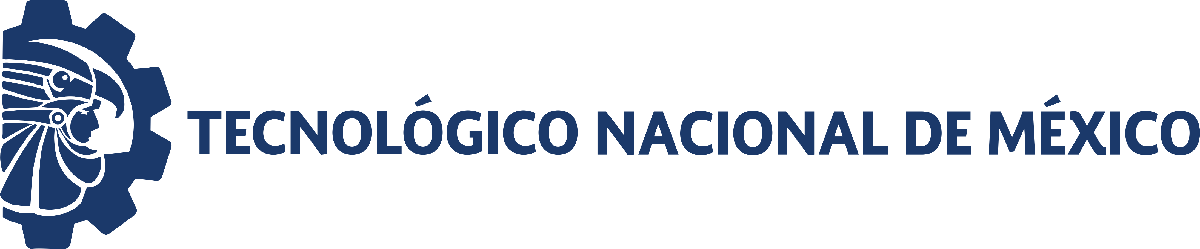                                 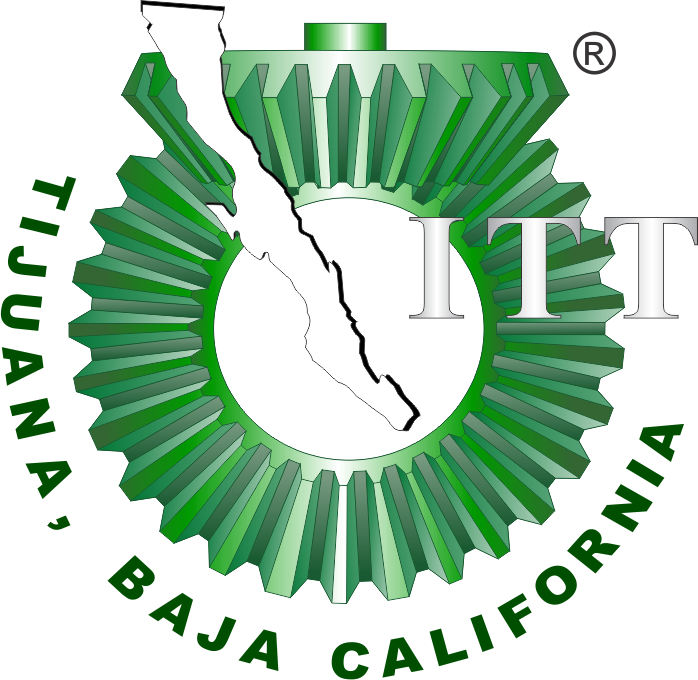

# Proyecto Final: Terapia de Presión Negativa

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

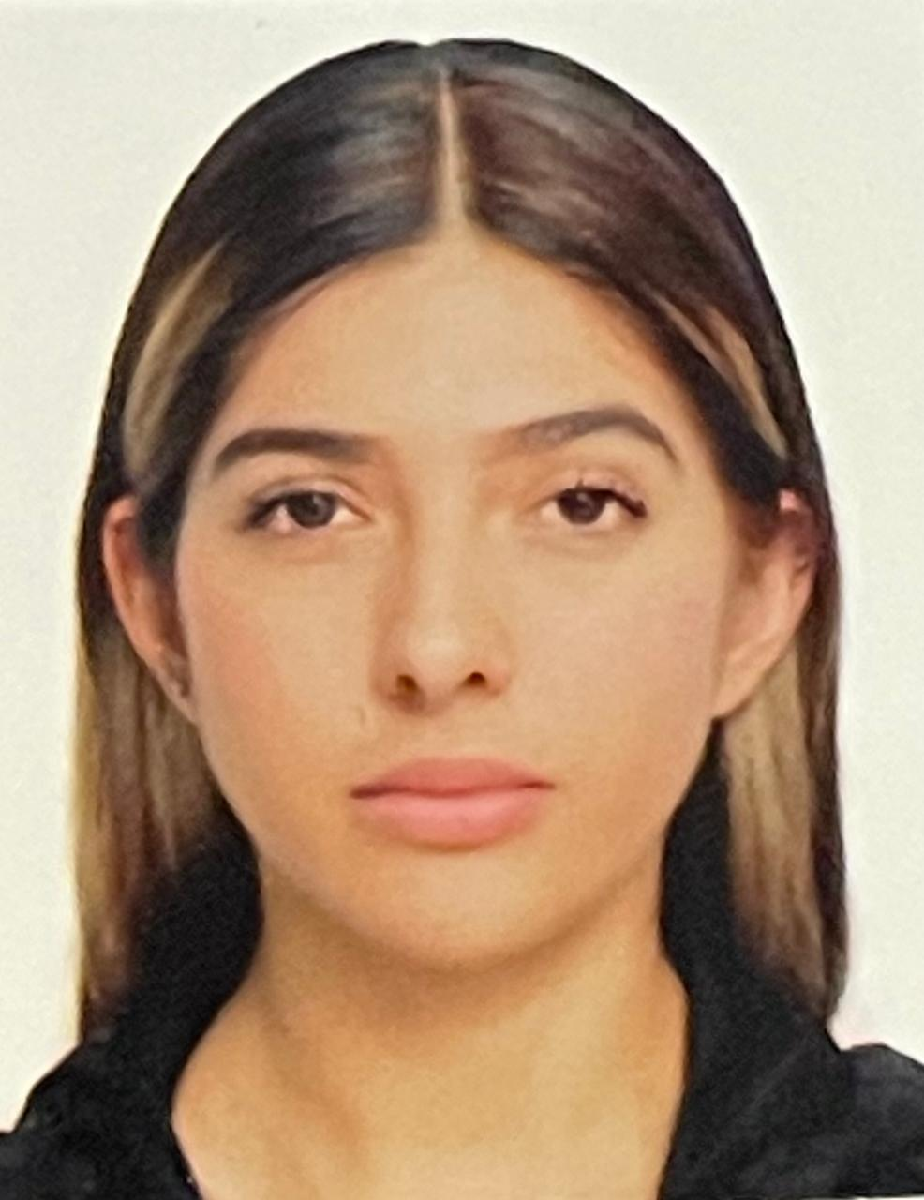

Nombre del alumno: **Josselin Gonzalez García**

Número de control: **C21210380**

Correo institucional: **l21210380@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '20'; 
file = 'TPN';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

## Rendimiento del controlador para Tratamiento

kP = 721.1926

kI = 271.4443

kD = 425.7384

Rise Time = 0.0334

Settling Time = 0.058

Overshoot = 0.293%

## Respuesta al escalón unitario

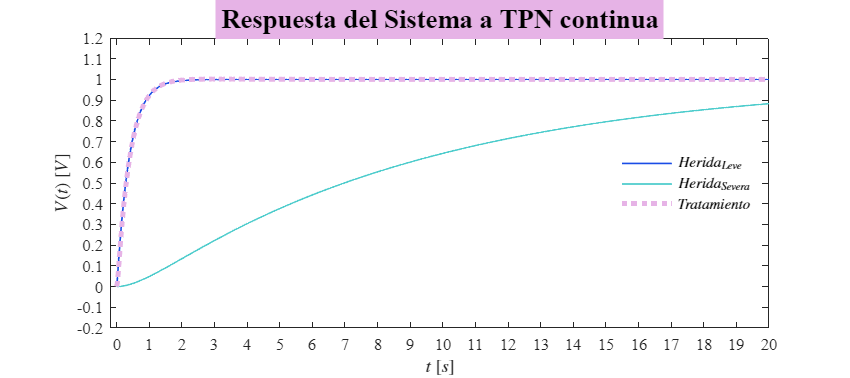

Signal = 'TPN Continua';
set_param('TPN/S1','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ppx,x1.Ppy,x1.Ppz,Signal) %to workspace buscar en el library browser del sysp0 
title('Respuesta del Sistema a TPN continua','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## Respuesta al impulso

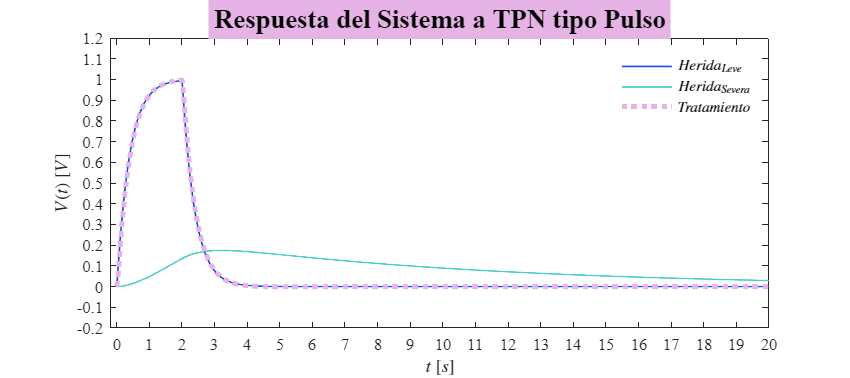

Signal = 'TPN a Pulsos';
set_param('TPN/S1','sw','0');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ppx,x2.Ppy,x2.Ppz,Signal) %to workspace buscar en el library browser del sysp0 
title('Respuesta del Sistema a TPN tipo Pulso','FontSize',16,'BackgroundColor',[0.9,0.7,0.9])

## **Función: Respuesta a las señales**

function plotsignals(t,Ppx,Ppy,Ppz,Signal)

    t = Ppx.Time;  % Asume que todos comparten el mismo tiempo
    Ppx = Ppx.Data;
    Ppy = Ppy.Data;
    Ppz = Ppz.Data;

    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10, 'points')
   %% am = [0.3,0.8,0.8];
    rf = [0.1,0.3,0.9];
    na = [0.9,0.7,0.9];
    hold on; grid off; box on

    plot(t,Ppy,'LineWidth',1,'Color',rf)
    plot(t,Ppx,'LineWidth',1,'Color',[0.3,0.8,0.8])
    plot(t,Ppz,':','LineWidth',3,'Color',na)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$V(t)$ $[V]$','Interpreter','Latex')

    L = legend('$Herida_{Leve}$','$Herida_{Severa}$','$Tratamiento$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    if Signal == 'TPN a Pulsos'
        xlim([-0.2,20]); xticks(0:1:20)  %dominio
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)  %rango
    elseif Signal == 'TPN Continua'
        xlim([-0.2,20]); xticks(0:1:20)
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end